# **RT-QIBC analysis**

**YFP1: Cdt1**

**YFP2: Geminin**

**YFP5: Cyclin A**

**FarRed1: EdU**

**POI(:,3): CRL4Cdt2 activation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
            'Cterm NR67',2:3,7:11,1:4,[0 0 0]; %1    
        'CA NR48',2:3,2:6,1:4,[0 0 0]; %1      
};


load([dataDir filesep 'C217_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/8;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};


**Set gates**

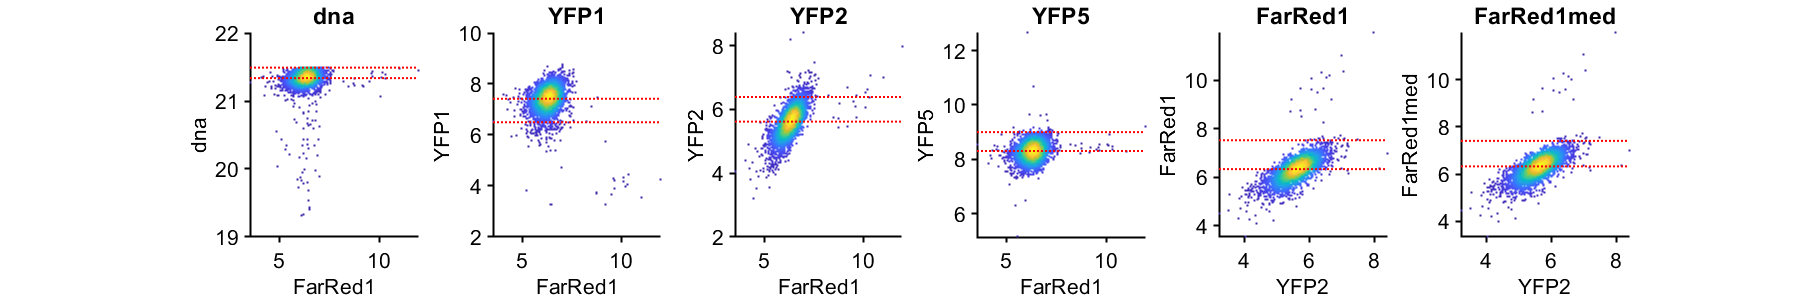


%% Set gates time after mitosis
cond=1;
gate = struct();
gates = {'dna','YFP1','YFP2','YFP5','FarRed1','FarRed1med'};
plotting = {'FarRed1','FarRed1','FarRed1','FarRed1','YFP2','YFP2'};
prctiles = {[50 99], [5 50],[50 95],[50 99],[50 99],[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) <= 2 & S(cond).POI_time(:,1) > 1 & S(cond).dna < 2^21.5;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    if strcmp(gates{i},'FarRed1')
        g1cellsedu = ydata;
    end
    if strcmp(gates{i},'YFP2')
        g1cellsgem = ydata;
    end
        if strcmp(gates{i},'YFP5')
        g1cellscyc = ydata;
    end
end

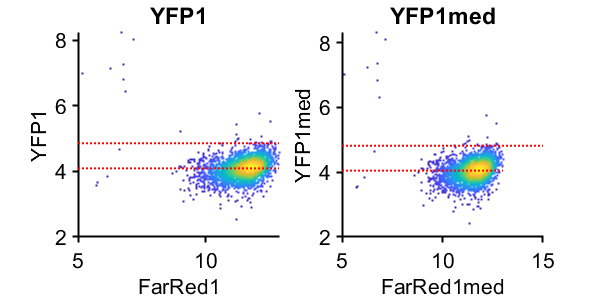



%% set S phase gates
cond=1;
gates = {'YFP1','YFP1med'};
plotting = {'FarRed1','FarRed1med'};
prctiles = {[50 99],[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,3) <= 2 &  S(cond).POI_time(:,3) > 1 ;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_S'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

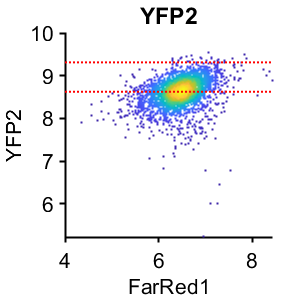


%% set G2 phase gates
cond=1;
gates = {'YFP2'};
plotting = {'FarRed1'};
prctiles = {[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,5) > 0 & S(cond).FarRed1 < 2*gate.FarRed1_G1(2) & S(cond).POI_time(:,3) < 10 ...
        & S(cond).YFP5 > 2^9.75;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G2']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G2'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    if strcmp(gates{i},'YFP2')
        g2cellsgem = ydata;
    end

end

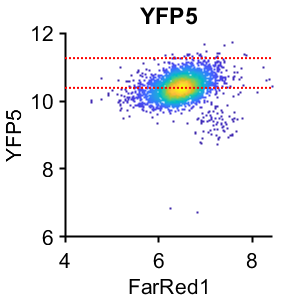


%% set G2 phase gates
cond=1;
gates = {'YFP5'};
plotting = {'FarRed1'};
prctiles = {[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,5) > 0 & S(cond).FarRed1 < 2*gate.FarRed1_G1(2) & S(cond).POI_time(:,3) < 10 ...
        & S(cond).YFP2 > 2^8;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G2']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G2'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});

   if strcmp(gates{i},'YFP5')
        g2cellscyc = ydata;
    end
end

**Time since CRL IF levels for export**

cond=1;
poiAligned=3;
offset=0;


rng(1)
gateVals = {{}};
rangeVals = {{[]}};

xrange = [0 8];

ind= ~isnan(S(cond).POI_time(:,poiAligned(1))) & ...
    gate_vals(S(cond), gateVals{1}, rangeVals{1})  & S(cond).POI_time(:,poiAligned(1)) <=8;

xdata = S(cond).POI_time(ind,poiAligned);
ydata = [];
ydata(:, 1) = (S(cond).YFP5(ind) - gate.YFP5_G1(1))/(1337 - gate.YFP5_G1(1));
ydata(:, 2) = (S(cond).YFP2(ind) - gate.YFP2_G1(1))/(gate.YFP2_G2(1)- gate.YFP2_G1(1));
ydata(:, 3) = (S(cond).FarRed1(ind)) - gate.FarRed1_G1(1);

length(xdata)

ans = 13262

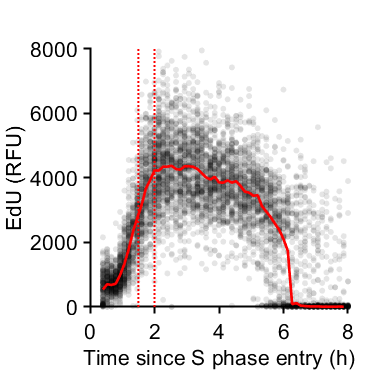

edges = unique(xdata);
[binData, edges] = bin_xy(xdata, ydata, {'mean','median'},...
    'Edges',edges);
midpoints = edges;
midpoints = midpoints(1:end-1);


f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
hold on
% subG1 = randsample(log2(g1cellsedu),300);
subs_cells = randsample(size(ydata,1),6000);
subs = false(size(ydata,1),1);
subs(subs_cells) = true;
subs = subs & ydata(:,2) < 2 & ydata(:,2) > -.1;
scatter(xdata(subs),ydata(subs,3),20,'k','filled','MarkerFaceAlpha',.1)
plot(midpoints,binData(3).median,'r','LineWidth',2);
ylim([0 8000]);
xlim([0 8]);
ylabel('EdU (RFU)');
xlabel({'Time since S phase entry (h)'});
vline([1.5 2])
axis square
hold off
print_pdf([pwd() '\Figs\EdU_point_int.pdf'])

t_points = [0:.05:midpoints(end)];
interp_x = [0 midpoints'];
interp_e = [0 binData(3).median];
e_points = interp1(interp_x, interp_e,t_points);
integrate_total = trapz(t_points,e_points);
integrate_range = trapz(t_points(31:41),e_points(31:41));
frac_EdU = integrate_range/integrate_total

frac_EdU = 0.0955


min(binData(1).numCells(binData(1).numCells > 0))

ans = 167

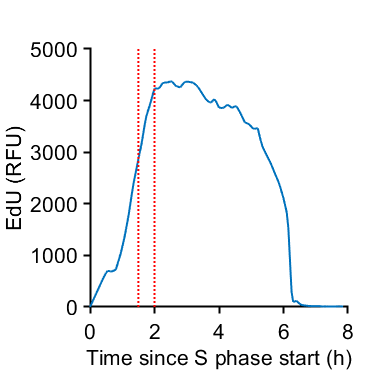


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
plot(t_points, e_points)
axis square
box off
ylabel('EdU (RFU)');xlabel('Time since S phase start (h)');
vline([1.5 2])
print_pdf([pwd() '\Figs\EdU_line_int.pdf'])

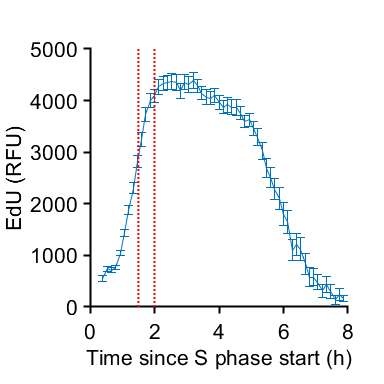


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
hold on
errorbar(midpoints, binData(3).mean,2*binData(3).sem)
axis square
box off
ylabel('EdU (RFU)');xlabel('Time since S phase start (h)');
vline([1.5 2])
print_pdf([pwd() '\Figs\EdU_line_sem.pdf'])

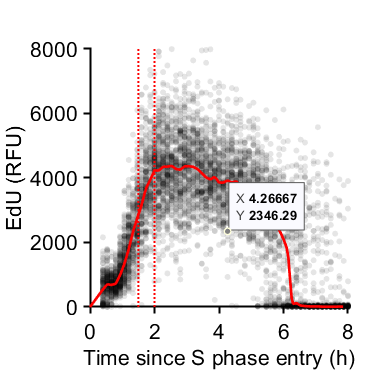


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
hold on
% subG1 = randsample(log2(g1cellsedu),300);
subs_cells = randsample(size(ydata,1),6000);
subs = false(size(ydata,1),1);
subs(subs_cells) = true;
subs = subs & ydata(:,2) < 2 & ydata(:,2) > -.1;
scatter(xdata(subs),ydata(subs,3),20,'k','filled','MarkerFaceAlpha',.1)
plot(t_points,e_points,'r','LineWidth',2);
ylim([0 8000]);
xlim([0 8]);
ylabel('EdU (RFU)');
xlabel({'Time since S phase entry (h)'});
vline([1.5 2])
axis square
box off
hold off
print_pdf([pwd() '\Figs\EdU_point_line.pdf'])